# Lab on image transform and compression

## Load and show the image

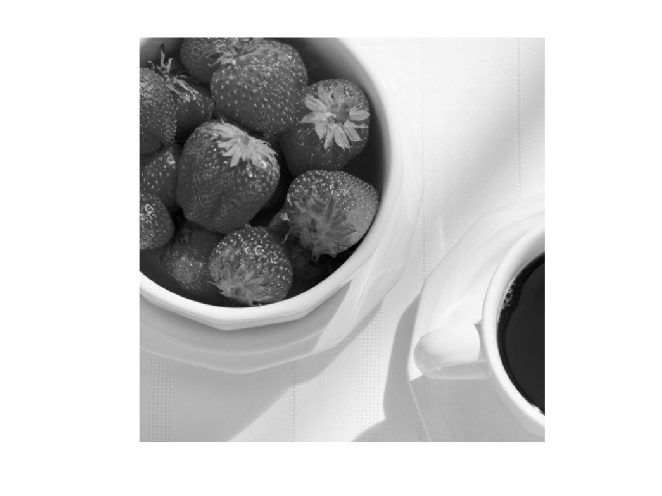

% Load the image 
fn = "coffee";
fileName = sprintf('%s.pgm',fn);
x= double(imread(fileName));
input_bpp = 8; % bits per pixel
dyn = 2^input_bpp; % Input image dynamics
[rows, cols] = size(x);
% Show the image
figure(1); image(x); colormap(gray); axis image; axis off; 

## Full-frame DFT 

We compute the 2D Discrete Fourier Transform over the whole image 

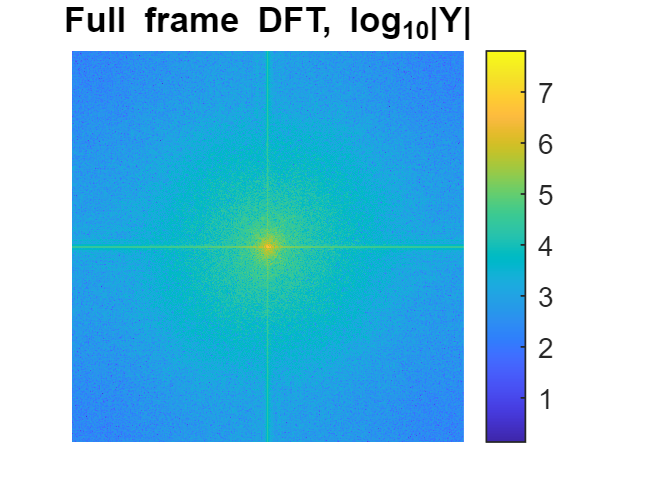

DFT = fft2(x); % Computes the 2D DFT using the FFT algorithm
centredSpectrum = fftshift(DFT); % Put frequency (0,0) at the center of the image
figure(2); imagesc(log10(abs(centredSpectrum))); % Display the spectrum
axis image; colorbar; axis off % Improved visualization
title('Full frame DFT, log_{10}|Y|');

## Histogram of the amplitude of the DFT coeffs

We compare the image histogram and the transform histogram.

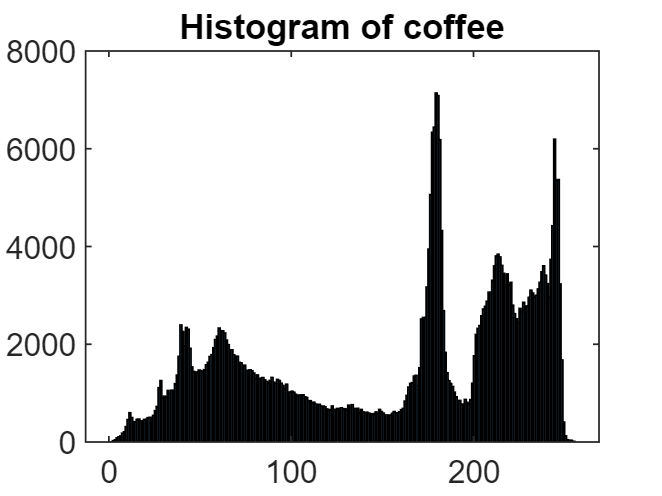

% Compute and show the image histogram
figure(3)
histogram(x(:),0:256); title(sprintf('Histogram of %s',fn) );

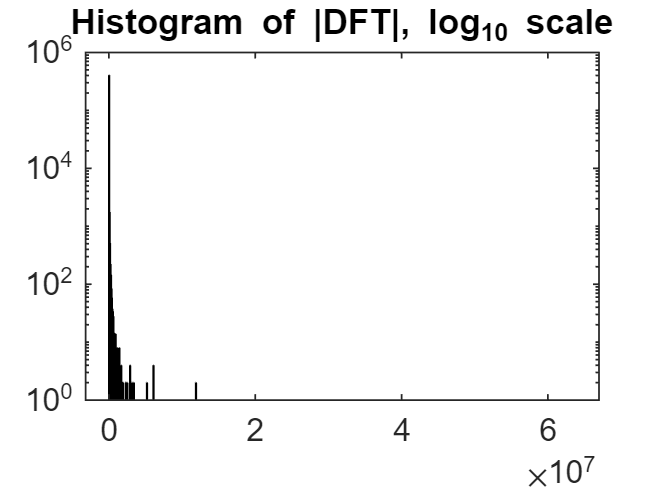

 
transfRange =  max(abs(DFT(:)));
nBins = 1e3;
bins = linspace(0,transfRange,nBins);
figure(4); 
histogram(abs(DFT),bins); set(gca,'YScale', 'Log')
title('Histogram of |DFT|, log_{10} scale');

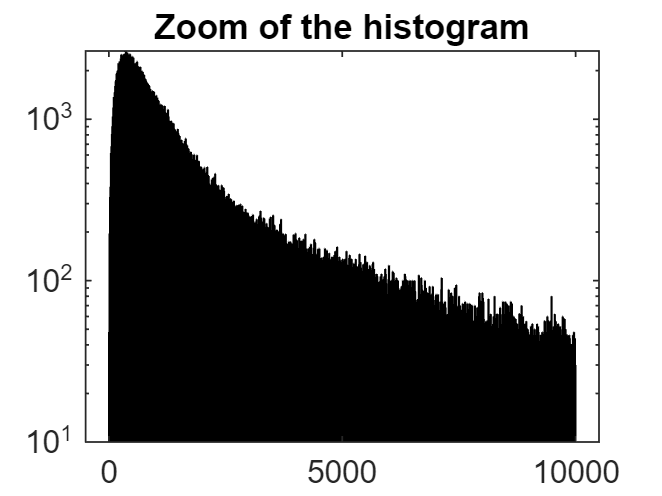

figure(5);
bins2 = linspace(0,1e4,nBins);
histogram(abs(DFT),bins2); set(gca,'YScale', 'Log')
title('Zoom of the histogram');

## Discrete Cosine Transform

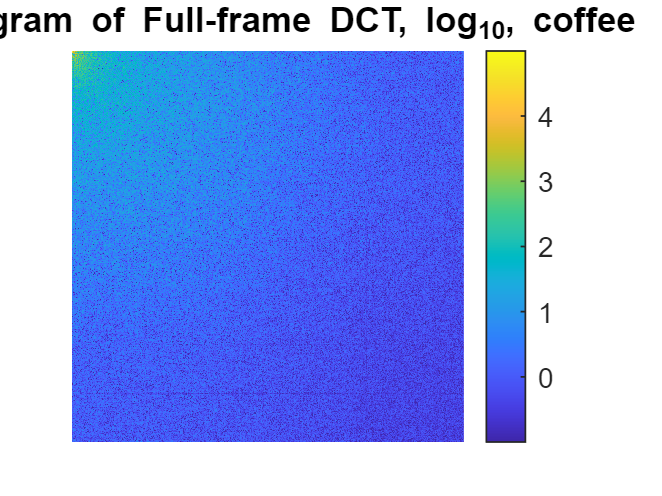

DCT = dct2(x);
figure(6); imagesc(log10(abs(DCT)+.1)); axis image; colorbar; axis off
title(sprintf('Full-frame DCT, log_{10}, %s',fn) );

## Draw histogram of DCT coeffs

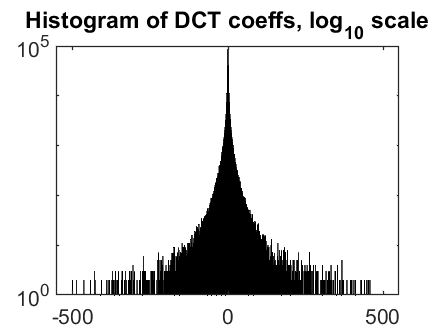

range = -5e2:5e2; %Manually set bins
figure(7); % Log-scale histogram
histogram(DCT,range);
set(gca,'YScale', 'Log')
title('Histogram of DCT coeffs, log_{10} scale');

## Block-based transform

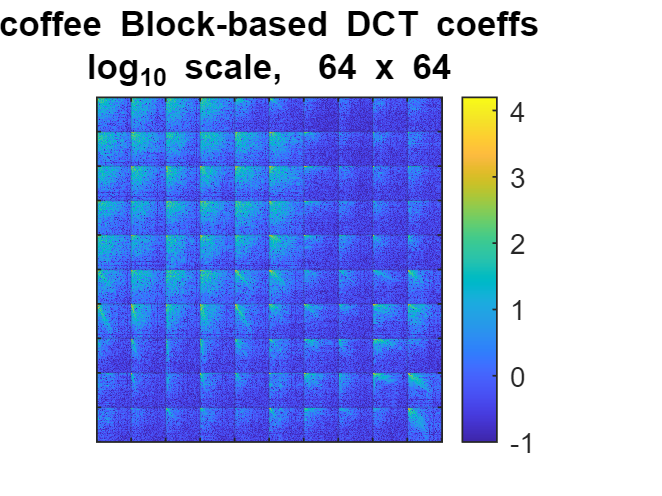

log2blockSize = 6;
blockSize = 2^log2blockSize; 
dctfun = @(block_struct) dct2(block_struct.data);
T_DCT = blockproc(x, [blockSize blockSize], dctfun);
figure(8); imagesc(log10(abs(T_DCT)+.1)); colorbar ; % Show DCT in logscale
title(sprintf('%s Block-based DCT coeffs\nlog_{10} scale,  %d x %d',...
    fn, blockSize,blockSize)); axis image
% Draw block borders
grid on;
set(gca, "XTick", 0:blockSize:cols,"YTick", 0:blockSize:rows)
set(gca, "YTickLabel",{}, "XTickLabel",{});

## Histogram of block-based DCT coefficients

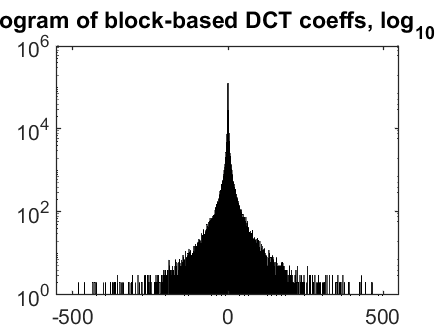

figure(9); 
range = -5e2:5e2;
histogram(T_DCT,range);
set(gca,'YScale', 'Log')
title('Hist. of block-based DCT coeffs, log_{10} scale');

## OPTIONAL: Compute the per-frequency variances and the coding gain

The block based DCT produces $N_B =\frac{N_{\textrm{impixels}} }{N_{\textrm{blpixels}} }$ blocks. 

log2blockSize = 3;
blockSize = 2^log2blockSize; 
fprintf('%2dx%2d blocks\n',blockSize,blockSize);

 8x 8 blocks


dctfun = @(block_struct) dct2(block_struct.data);
T_DCT = blockproc(x, [blockSize blockSize], dctfun);

numBlocks = rows*cols/ blockSize / blockSize; 

Each block is considered as a random vector, and each component is a random variable with its onw variance ${\sigma_i }^2$

**The geometric mean (GM)** of these variances is related to the transform coding gain, ie. the gain in distortion reduction achievable with transform coding. Since the Coding Gain is :$\textrm{CG}=\frac{\sigma_{\textrm{AM}}^2 }{\sigma_{\textrm{GM}}^2 }\;\;$, then the smaller the GM, the larger the coding gain.

The geometric mean is also a measure of sparsity, since it gets smaller for sparse data. 

Let us then compute the GM and the arithmetic mean (AM) of these variances. We start by creating a suitable data structure: a rectangular cuboid in which each slice is a block of DCT coefficients

cuboid = zeros(blockSize, blockSize, numBlocks); % A zero-filled 3D matrix
n=0;
for r = 0:blockSize:rows-1     % scan the image block-by-block
    for c = 0:blockSize:cols-1
        n=n+1;
        block = T_DCT(r+1:r+blockSize, c+1:c+blockSize); %Take n-th block
        cuboid(:,:,n) = block; %...and put it in the n-th channel of the 3D matrix
    end
end

Let us now draw the cuboid of DCT coeffs. We subsample the blocks for ease of visualization; 

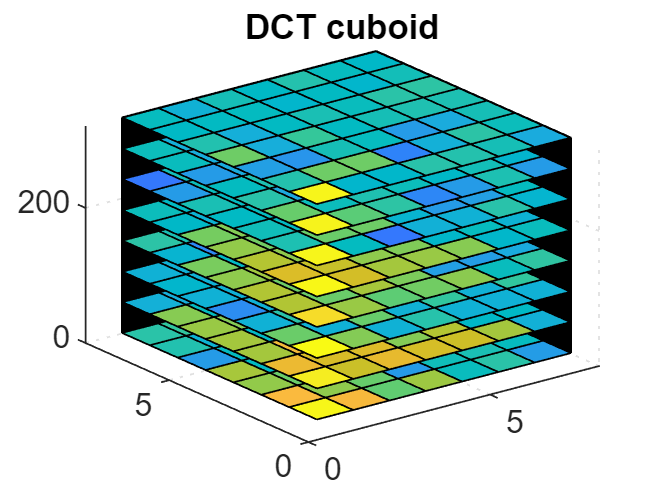

subSampling=min(20, numBlocks/4); 
nSlices = min(8,numBlocks/subSampling); 
xslice =   blockSize;
yslice =   blockSize;
zslice = round( linspace(1, numBlocks/subSampling, nSlices));
figure(10);  
slice(log10(abs(cuboid(:,:,1:subSampling:numBlocks)+.1)),xslice,yslice,zslice);
set(gca,"GridLineStyle",":"); 
title('DCT cuboid'); 

It is adviced to open the DCT cuboid figure in a window and maximize it to better look at it, in particular for large block sizes. 

The vertical coordinate is the number of block. The horizontal coordinates x and y are the spatial frequencies in each block. The DC component is in (0,0) 

Now we compute the variances of each frequency component: we just compute the variance along the vertical axis in the cuboid.

We create the output variable `vars` which has the same size of a block. 

vars =zeros(blockSize);

Then, for each frequency (indexed by `i` and `j`) we extract from the cuboid the vector of all the coefficients corresponding to that frequency and we compute the variance along this vector, named `tmp `

for i=1:blockSize
    for j = 1:blockSize
        tmp = cuboid(i,j,:); %take all the coeffs at the same freq i,j
        vars(i,j) = var(tmp(:)); %compute the variance of the subband
    end
end

Finally we display the result:

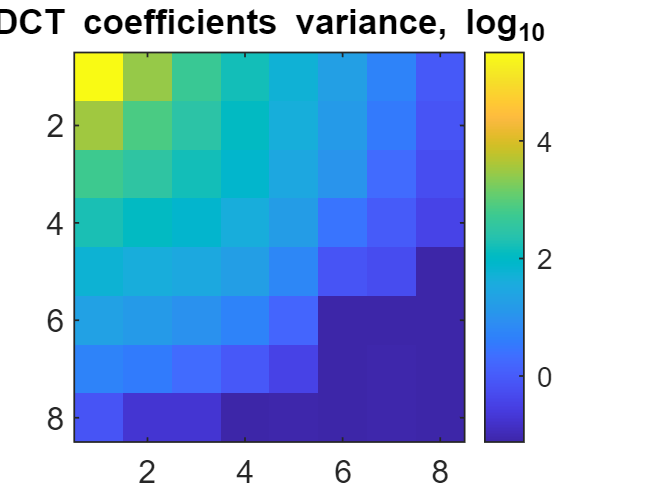

figure(11); imagesc(log10(vars)); colorbar; axis image; 
title('DCT coefficients variance, log_{10}');

Now we compute the Coding Gain:


$$\textrm{CG}=\frac{\sigma_{\textrm{AM}}^2 }{\sigma_{\textrm{GM}}^2 }\;\;$$


codingGain = mean2(vars) / exp(mean2(log(vars)));
CG_dB = 10*log10(codingGain);
fprintf('Coding gain: %4.2f dB\n', CG_dB);

Coding gain: 29.35 dB
